% 1. 读取图像
img = imread('image_152.png');  % 替换为你的图片路径
if size(img, 3) == 3
    img = rgb2gray(img);  % 转换为灰度图像
end

% 2. 对图像进行傅里叶变换
F = fft2(double(img));  % 傅里叶变换
F_shifted = fftshift(F);  % 移动零频到中心
magnitude_spectrum = log(1 + abs(F_shifted));  % 取频谱的幅值

% 3. 计算高频分量占比
[rows, cols] = size(img);
center_row = floor(rows / 2);
center_col = floor(cols / 2);
radius = min(center_row, center_col) / 4;  % 定义一个半径
[X, Y] = meshgrid(1:cols, 1:rows);
distance = sqrt((X - center_col).^2 + (Y - center_row).^2);

% 高频区域（距离中心大于radius的部分）
high_freq = distance > radius;
high_freq_energy = sum(sum(abs(F_shifted(high_freq)).^2));
total_energy = sum(sum(abs(F_shifted).^2));

% 高频能量占比
high_freq_ratio = high_freq_energy / total_energy;

% 4. 判断模糊程度
threshold = 0.1;  % 设置一个经验阈值
if high_freq_ratio < threshold
    disp('图片是模糊的');
else
    disp('图片是清晰的');
end

图片是模糊的


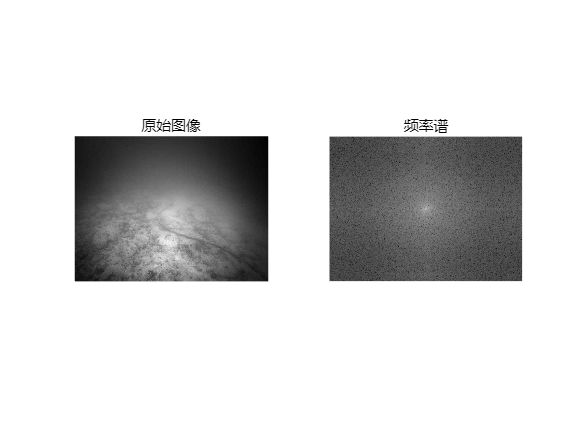


% 5. 可视化频谱
figure;
subplot(1, 2, 1);
imshow(img, []);
title('原始图像');

subplot(1, 2, 2);
imshow(magnitude_spectrum, []);
title('频率谱');